% The steps of the project

% 1. Face Detection: Use face detection algorithms to find the face within the image.
% 2. Feature Detection: Apply feature detection algorithms to locate the eyes and mouth.
% 3. Geometric Transformation: Apply transformations to rotate, scale, and translate the image so that the eyes (and if possible, the mouth) are aligned to a standard template.
% 4. Cropping and Resizing: Crop the aligned face to a standard size and resize it if necessary.
% 5. PCA and Eigenface Generation: Once the images are normalized and aligned, proceed with PCA and eigenface generation as you've already done.
% 6. Recognition: When a new image is received, apply the same preprocessing steps to it before projecting it onto the eigenface space for recognition.

## Daniels input

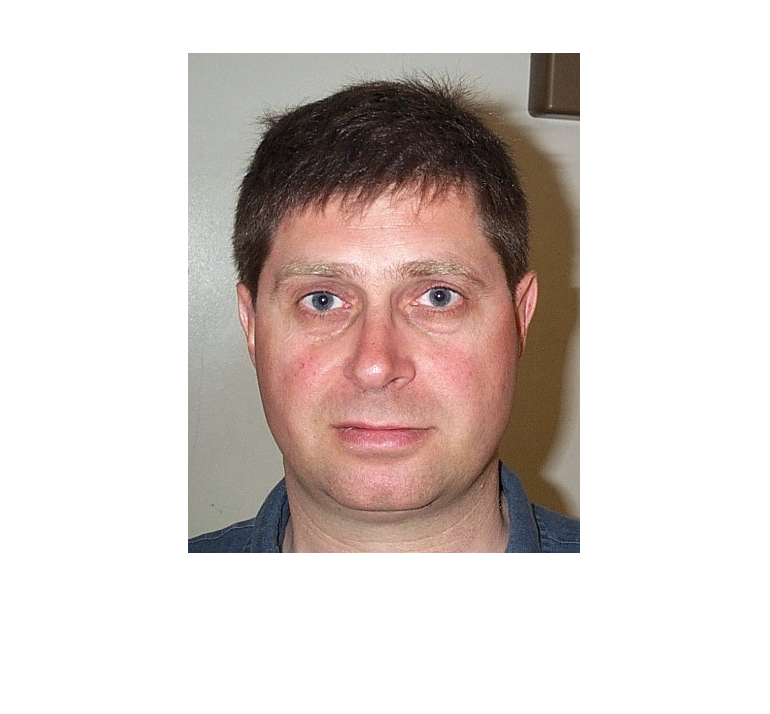

% DB1
testImage = imread('images/DB1/db1_01.jpg');
queryImagePath = 'images/DB1/db1_01.jpg';

% DB2
% queryImagePath = 'images/DB2/bl_01.jpg';
imshow(testImage);

%editedImage = degrade_img(testImage);
editedImage = testImage;

## Compensation

imshow(editedImage);


%editedImage = tone_compensation(editedImage);

## "Databas"

addpath('functions');

% Parameters
numImages = 16;
commonSize = [400, 300];
folderPath = 'images/DB1';
threshold = 0.90;  % Threshold for variance explanation

% Load and preprocess images
[dataMatrix, imageFiles] = load_and_preprocess_images(folderPath, commonSize);

% Perform PCA
[score, meanFace, numEigenfaces, eigenfaces, numComponentsRequired] = perform_pca(dataMatrix, threshold);

% Display number of components required
fprintf('Number of principal components needed: %d\n', numComponentsRequired);

Number of principal components needed: 10


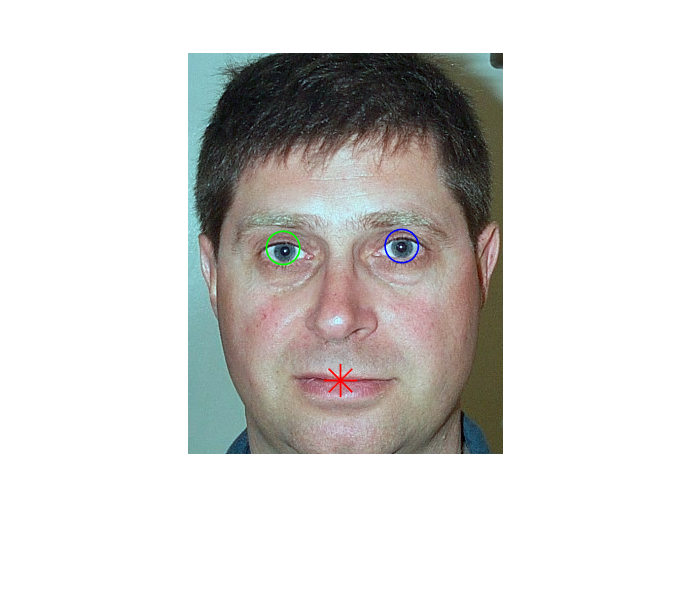

addpath('functions');
addpath('Images');



% Main-file
% img1 = imread("images/DB1/db1_01.jpg");
% img2 = imread("images/DB1/db1_02.jpg");
% img3 = imread("images/DB1/db1_03.jpg");


% PART 1 (purpose to find eyes)

% Load dataset
%editedImage = imread("Images\DB1\db1_01.jpg");
%imshow(editedImage)

eyes = find_eyes(editedImage);

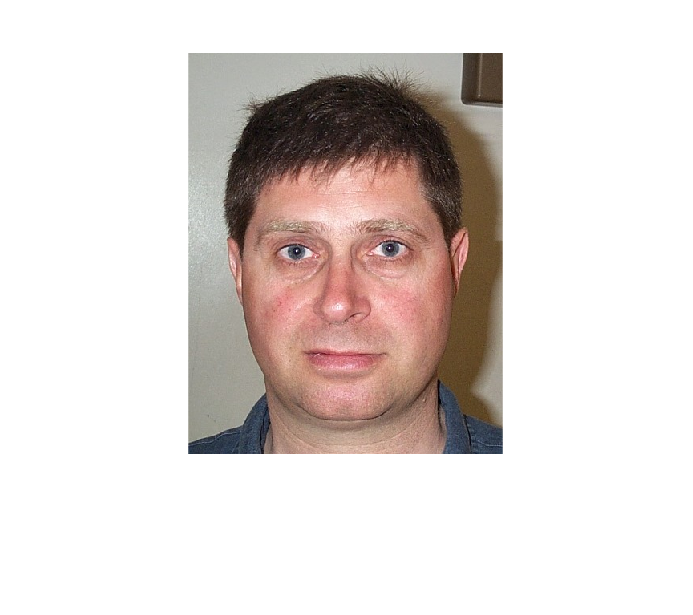


% Project query image onto eigenfaces
imshow(editedImage);

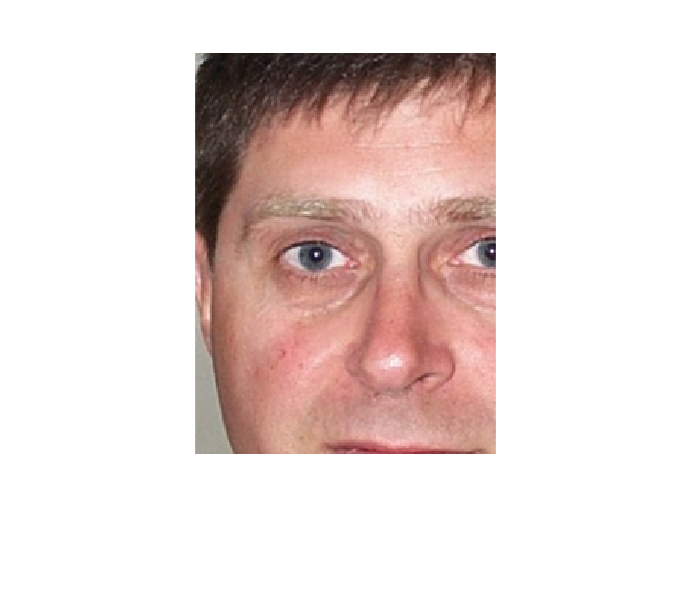

%im_comp = im2double(editedImage);
img_comp = rotation_compensation(editedImage, eyes);
imshow(img_comp)



queryWeights = project_onto_eigenfaces(queryImagePath, eigenfaces, meanFace, commonSize);

queryImgVector = 1×120000 uint8 row vector
   171   172   174   172   175   177   176   174   171   172   175   176   173   172   174   175   174   174   175   174   178   177   173   175   177   176   176   178   176   177   175   176   177   175   177   179   179   179   177   175   175   176   178   177   176   175   177   179   178   177


The query image matches with image #1 in the training set.


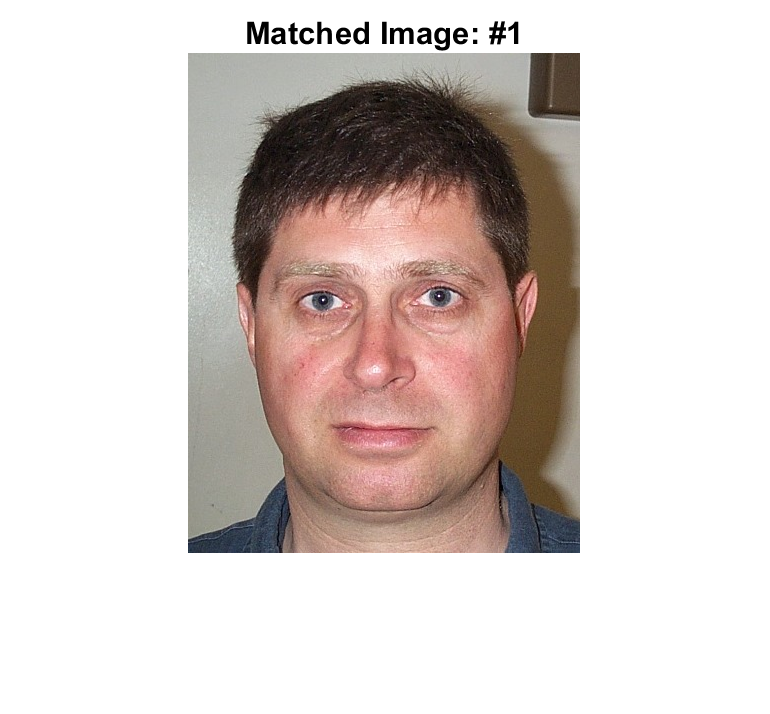


% Recognize the face
recognize_face(queryWeights, score, numImages, folderPath, imageFiles, numEigenfaces);